# **Practice 1: Analysis of the Temporary Response of a Digital Control System**

The practices of the subject Computer Control consist in the study of a servomechanism of angular positioning (LJ Technical Systems) controlled by a PC. The laboratory sessions P1 and P2 focus on the experimental analysis of the temporal and frequency responses of the system respectively. Sessions P3 and P4 are dedicated to the design of PID controllers. Finally, in practice P5 controllers will be designed in the frequency domain.

**OBJETIVE: Analysis of the temporal response of a digital control system for different sampling periods. Analysis of precision and stability.**

**In this session the student has to:**

- **Become familiar with the system: with the continuous time plant and with the use of the computer as signal generator, oscilloscope and digital controller.**

- **Evaluate the performance (accuracy and stability) of the system based on the sampling period.**

% Alternate between the experiment data and the directory Results
% If you want to use the data in the directory Results = false
% If you want to use your own data = true
useExperimentalData = false;

# Ejercise 1: Open-loop system response for the tachometer signal.

Open and execute the model P1_Ex1.slx. Check that it is the typical response of a first-order system and how the static gain varies if we apply the magnetic brake to the motor. Identify the time constant and the static gain for a step input of 1V.

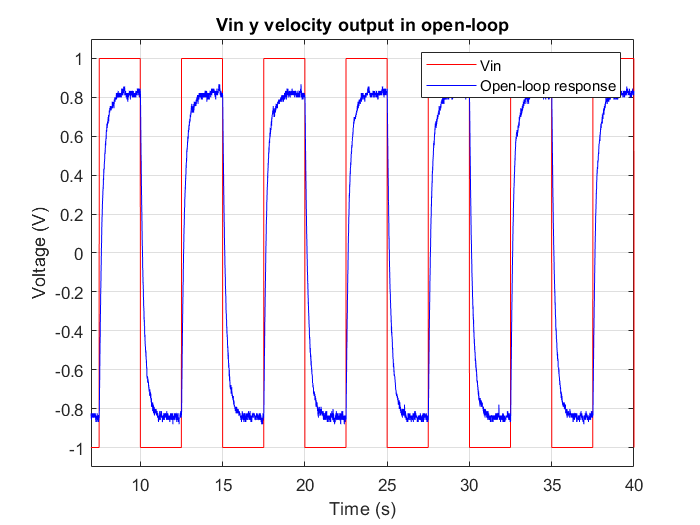

% Initialization of variables
Tg=0.005; % Graphing time [seg]
Vmax=5; % [V]
Vmin=-5; % [V]

% Draw the response of the motor
if useExperimentalData
    % Use Simulink
    addpath([pwd filesep 'E1']);
    open P1_Ex1.slx;
    run P1_Ex1.slx;
else
    FileName   = 'OpenLoopResponse.mat';
    cd('..')
    FolderName = [pwd filesep 'Common' filesep 'Resultados' filesep 'Prac1' filesep 'Ex1'];
    File       = fullfile(FolderName, FileName);
    load(File);   
end

figure
plot(OpenLoopResponse.time,[OpenLoopResponse.signals.values(:,1,:)],'r')
hold on
plot(OpenLoopResponse.time,[OpenLoopResponse.signals.values(:,2,:)],'b')
xlim([7 40]); ylim([-1.1 1.1]);
grid on
xlabel('Time (s)');
ylabel('Voltage (V)');
title('Vin y velocity output in open-loop');
legend('Vin','Open-loop response');

% Application of the brake in open loop
if useExperimentalData
    % Use Simulink 
    addpath([pwd filesep 'E1']);
    open P1_Ex1.slx;
    run P1_Ex1.slx;
else
    FileName   = 'OpenLoopBrake.mat';
    FolderName = [pwd filesep 'Common' filesep 'Resultados' filesep 'Prac1' filesep 'Ex1'];
    File       = fullfile(FolderName, FileName);
    load(File);   
end

As we can see, the output resembles the response of a first order system, so the structure of its transfer function will follow the structure of:


$$\frac{V_{\mathrm{out}} \left(s\right)}{V_{\mathrm{in}} \left(s\right)}=\frac{k}{\tau s+1}$$


For this case study, the following transfer function has been obtained.


$$\frac{V_{\textrm{out}} \left(s\right)}{V_{\textrm{in}} \left(s\right)}=\frac{0\ldotp 82}{0\ldotp 26s+1}$$


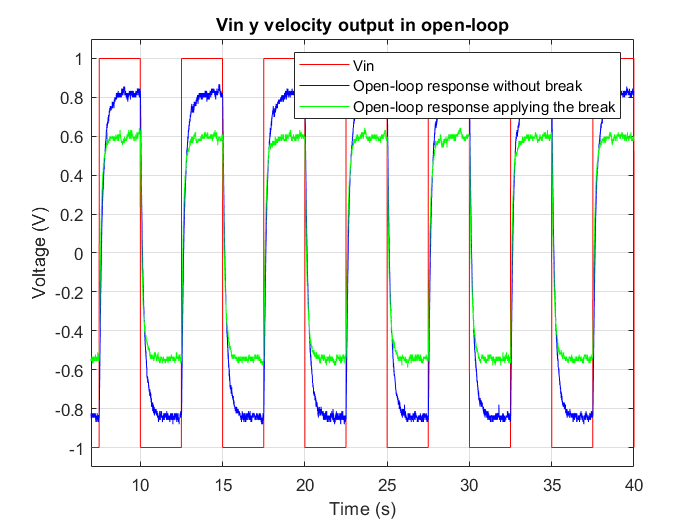

figure
plot(OpenLoopResponse.time,[OpenLoopResponse.signals.values(:,1,:)],'r')
hold on
plot(OpenLoopResponse.time,[OpenLoopResponse.signals.values(:,2,:)],'b')
plot(OpenLoopBrake.time,[OpenLoopBrake.signals.values(:,2,:)],'g')
xlim([7 40]); ylim([-1.1 1.1]);
grid on
xlabel('Time (s)');
ylabel('Voltage (V)');
title('Vin y velocity output in open-loop');
legend('Vin','Open-loop response without break','Open-loop response applying the break');

Furthermore, in the case of open loop, this gain varies depending on the brake. As you can see in the image, if we apply the brake, the gain will be considerably reduced.

# Ejercise 2: System's response in closed-loop with velocity feedback.

Open and execute the model P1_Ex2.slx. Check how the error in steady state varies for Kp = 1, 2 and 5, changing the "Proportional Controller" block.

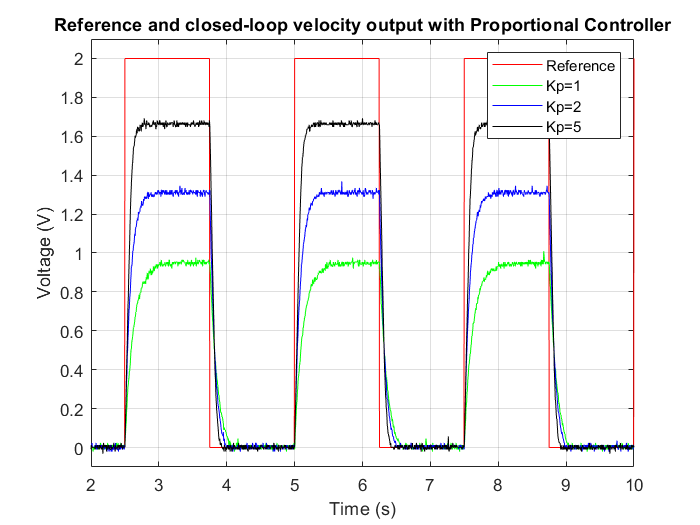

% Initialization of variables
Tg=0.005; % Graphing time [seg]
Vmax=5; % [V]
Vmin=-5; % [V]

if useExperimentalData
    % Use Simulink 
    addpath([pwd filesep 'E2']);
    open P1_Ex2.slx;
    run P1_Ex2.slx;
else % Load variables
    FileName   = 'Kp1.mat';
    FolderName = [pwd filesep 'Common' filesep 'Resultados' filesep 'Prac1' filesep 'Ex2'];
  %  FolderName = [pwd filesep '..' filesep '..' filesep 'Resultados' filesep 'Prac1' filesep 'Ex2'];
    File       = fullfile(FolderName, FileName);
    load(File); 
    
    FileName   = 'Kp2.mat';
    FolderName = [pwd filesep 'Common' filesep 'Resultados' filesep 'Prac1' filesep 'Ex2'];
    File       = fullfile(FolderName, FileName);
    load(File);
    
    FileName   = 'Kp5.mat';
    FolderName = [pwd filesep 'Common' filesep 'Resultados' filesep 'Prac1' filesep 'Ex2'];
    File       = fullfile(FolderName, FileName);
    load(File); 
end


% output signal
figure
plot(Kp1.time,[Kp1.signals.values(:,3,:)],'r') 
hold all
plot(Kp1.time, [Kp1.signals.values(:,1,:)],'g')
plot(Kp2.time, [Kp2.signals.values(:,1,:)],'b')
plot(Kp5.time, [Kp5.signals.values(:,1,:)],'k')
xlim([2 10]); ylim([-0.1 2.1]);
grid on
xlabel('Time (s)');
ylabel('Voltage (V)');
title('Reference and closed-loop velocity output with Proportional Controller');
legend('Reference','Kp=1','Kp=2','Kp=5');

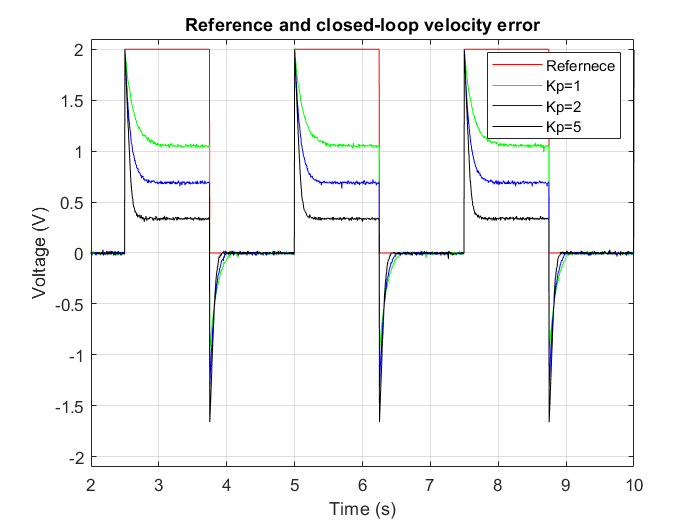


% Error signal
figure
plot(Kp1.time,[Kp1.signals.values(:,3,:)],'r') 
hold all
plot(Kp1.time, [Kp1.signals.values(:,2,:)],'g')
plot(Kp2.time, [Kp2.signals.values(:,2,:)],'b')
plot(Kp5.time, [Kp5.signals.values(:,2,:)],'k')
xlim([2 10]); ylim([-2.1 2.1]);
grid on;
xlabel('Time (s)');
ylabel('Voltage (V)');
title('Reference and closed-loop velocity error');
legend('Refernece','Kp=1','Kp=2','Kp=5');

As you can see in the previous images, the higher the Kp, the faster the response and the smaller the steady state error.

# Exercise 3: Experimental evaluation of the performance of the closed loop system with velocity feedback. 

Open and execute the model P1_Ex3.slx. Evaluate how the accuracy and stability of the system varies for different sampling periods.

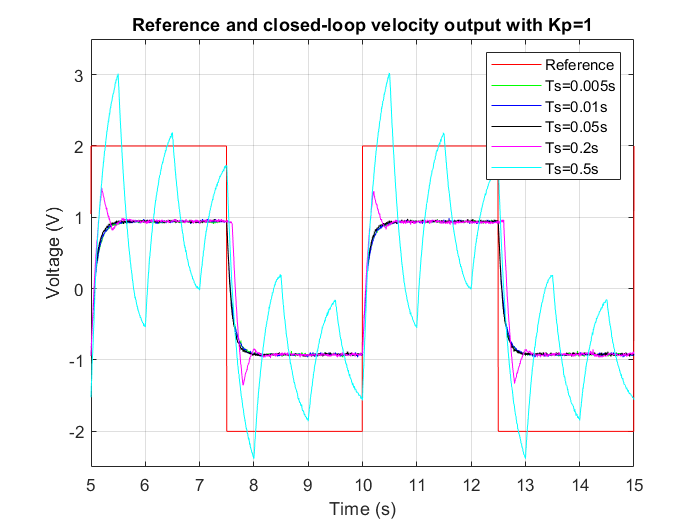

% Initialization of variables
Tg=0.005; % Graphing time [seg]
Ts=0.01; % Sampling time
Vmax=5; % [V]
Vmin=-5; % [V]

if useExperimentalData
    % Use Simulink 
    addpath([pwd filesep 'E3']);
    open P1_Ex3.slx;
    run P1_Ex3.slx;
else % Load variables
    FileName   = 'Ts5ms.mat';
    FolderName = [pwd filesep 'Common' filesep 'Resultados' filesep 'Prac1' filesep 'Ex3'];
    File       = fullfile(FolderName, FileName);
    load(File);   

    FileName   = 'Ts10ms.mat';
    FolderName = [pwd filesep 'Common' filesep 'Resultados' filesep 'Prac1' filesep 'Ex3'];
    File       = fullfile(FolderName, FileName);
    load(File);
    
    FileName   = 'Ts50ms.mat';
    FolderName = [pwd filesep 'Common' filesep 'Resultados' filesep 'Prac1' filesep 'Ex3'];
    File       = fullfile(FolderName, FileName);
    load(File);
    
    FileName   = 'Ts02s.mat';
    FolderName = [pwd filesep 'Common' filesep 'Resultados' filesep 'Prac1' filesep 'Ex3'];
    File       = fullfile(FolderName, FileName);
    load(File);
    
    FileName   = 'Ts05s.mat';
    FolderName = [pwd filesep 'Common' filesep 'Resultados' filesep 'Prac1' filesep 'Ex3'];
    File       = fullfile(FolderName, FileName);
    load(File);
end


% output
figure()
plot(Ts5ms.time,[Ts5ms.signals.values(:,2,:)],'r')
hold all
plot(Ts5ms.time, [Ts5ms.signals.values(:,3,:)],'g')
plot(Ts10ms.time, [Ts10ms.signals.values(:,3,:)],'b')
plot(Ts50ms.time, [Ts50ms.signals.values(:,3,:)],'k')
plot(Ts02s.time, [Ts02s.signals.values(:,3,:)],'m')
plot(Ts05s.time, [Ts05s.signals.values(:,3,:)],'c')
xlim([5 15]);ylim([-2.5 3.5]);
grid on;
xlabel('Time (s)');
ylabel('Voltage (V)');
title('Reference and closed-loop velocity output with Kp=1');
legend('Reference','Ts=0.005s','Ts=0.01s','Ts=0.05s','Ts=0.2s','Ts=0.5s')

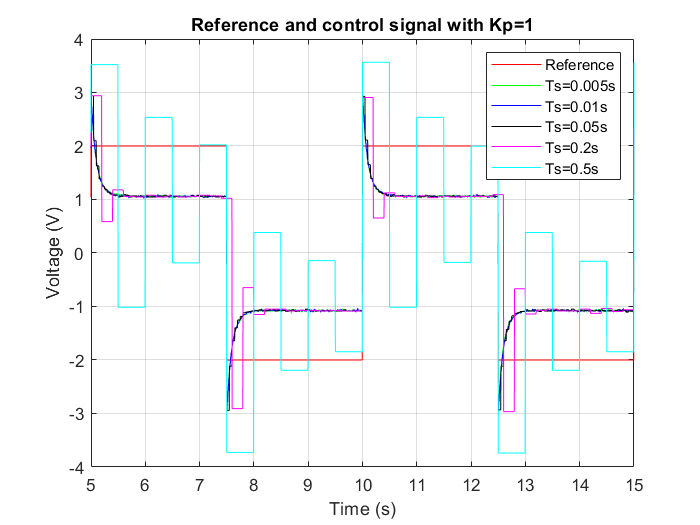


% error
figure()
plot(Ts5ms.time,[Ts5ms.signals.values(:,2,:)],'r')
hold all
plot(Ts5ms.time, [Ts5ms.signals.values(:,1,:)],'g')
plot(Ts10ms.time, [Ts10ms.signals.values(:,1,:)],'b')
plot(Ts50ms.time, [Ts50ms.signals.values(:,1,:)],'k')
plot(Ts02s.time, [Ts02s.signals.values(:,1,:)],'m')
plot(Ts05s.time, [Ts05s.signals.values(:,1,:)],'c')
xlim([5 15]);ylim([-4 4]);
grid on;
xlabel('Time (s)');
ylabel('Voltage (V)');
title('Reference and control signal with Kp=1');
legend('Reference','Ts=0.005s','Ts=0.01s','Ts=0.05s','Ts=0.2s','Ts=0.5s')

To analyze from which Ts we will have oscillations, we must obtain the digital transfer function of the closed-loop system. For this, first, the open loop digital transfer function will be calculated using a zero-order holder. 

Once the pole expression is obtained, we will equal it to zero, since the system will begin to oscillate at that precise moment. In this case, evaluating the equation with our parameters, we obtain that the system starts to oscillate at 0.2 seconds of sampling time and as you can see in the image, the response of the system with this sampling period, the magenta response, presents an overshoot. At longer sampling times, the output is even more oscillating. 

# Exercise 4: Open-loop system response for the potentiometer signal.

Open and execute the model P1_Ex4.slx. Check that is the typical response of a type 1 system. 

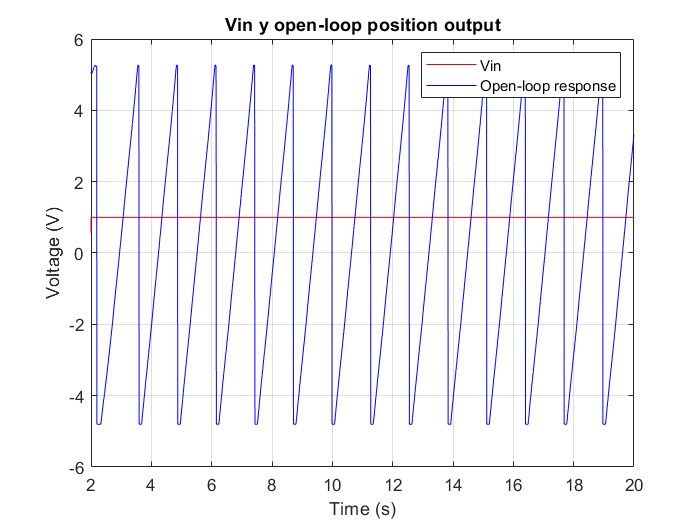

% Initialization of variables
Tg=0.005; % Graphing time [seg]
Vmax=5; % [V]
Vmin=-5; % [V]

if useExperimentalData
    % Use Simulink 
    addpath([pwd filesep 'E4']);
    open P1_Ex4.slx
    run P1_Ex4.slx
else % Load open-loop response
    FileName   = 'OpenLoopPosition.mat';
    FolderName = [pwd filesep 'Common' filesep 'Resultados' filesep 'Prac1' filesep 'Ex4'];
    File       = fullfile(FolderName, FileName);
    load(File);   
end

% output
figure
plot(OpenLoopPosition.time,[OpenLoopPosition.signals.values(:,1,:)],'r')
hold on
plot(OpenLoopPosition.time,[OpenLoopPosition.signals.values(:,2,:)],'b')
xlim([2 20]);grid on;
xlabel('Time (s)');
ylabel('Voltage (V)');
title('Vin y open-loop position output');
legend('Vin','Open-loop response');

In this case, the response of the plant in open loop is a periodic signal with saw wave form, since the plant is of type 1. With which, to step type inputs we will obtain a ramp type signal. On the other hand, the periodicity occurs for each spin of the potentiometer axis.

# Exercise 5: Closed-loop system's response with position feedback.

Open and execute the model P1_Ex5.slx. Check how the response varies for Kp = 1, 2 and 3, changing the "Proportional Controller" block.

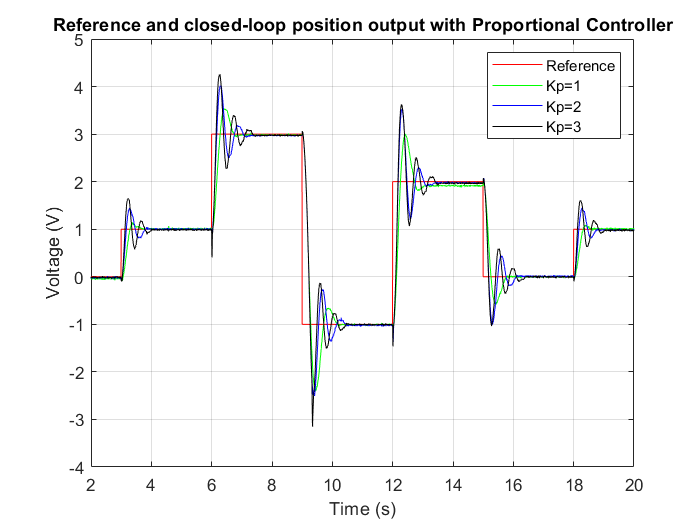

% Initialization of variables
Tg=0.005; % Graphing time [seg]
Vmax=5; % [V]
Vmin=-5; % [V]

if useExperimentalData
    % Use Simulink 
    addpath([pwd filesep 'E5']);
    open P1_Ex5.slx
    run P1_Ex5.slx
else % Load variables
    FileName   = 'Kp1.mat';
    FolderName = [pwd filesep 'Common' filesep 'Resultados' filesep 'Prac1' filesep 'Ex5'];
    File       = fullfile(FolderName, FileName);
    load(File);   
    
    FileName   = 'Kp2.mat';
    FolderName = [pwd filesep 'Common' filesep 'Resultados' filesep 'Prac1' filesep 'Ex5'];
    File       = fullfile(FolderName, FileName);
    load(File);
    
    FileName   = 'Kp3.mat';
    FolderName = [pwd filesep 'Common' filesep 'Resultados' filesep 'Prac1' filesep 'Ex5'];
    File       = fullfile(FolderName, FileName);
    load(File);
end

% output
figure
plot(Kp1.time,[Kp1.signals.values(:,3,:)],'r') 
hold all; grid on;
plot(Kp1.time, [Kp1.signals.values(:,1,:)],'g')
plot(Kp2.time, [Kp2.signals.values(:,1,:)],'b')
plot(Kp3.time, [Kp3.signals.values(:,1,:)],'k')
xlim([2 20]);
xlabel('Time (s)');
ylabel('Voltage (V)');
title('Reference and closed-loop position output with Proportional Controller');
legend('Reference','Kp=1','Kp=2','Kp=3');

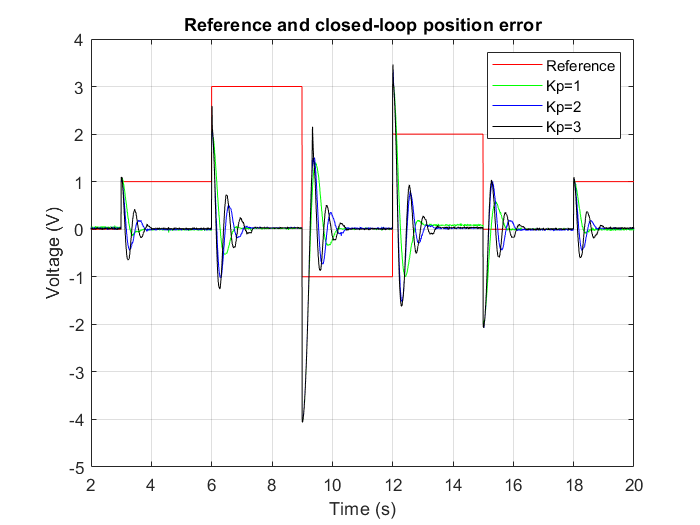


% error
figure
plot(Kp1.time,[Kp1.signals.values(:,3,:)],'r') 
hold all; grid on;
plot(Kp1.time, [Kp1.signals.values(:,2,:)],'g')
plot(Kp2.time, [Kp2.signals.values(:,2,:)],'b')
plot(Kp3.time, [Kp3.signals.values(:,2,:)],'k')
xlim([2 20]);
xlabel('Time (s)');
ylabel('Voltage (V)');
title('Reference and closed-loop position error');
legend('Reference','Kp=1','Kp=2','Kp=3');

In this case, as the engine is type 1, the steady-state error will be zero, but the overshoot and the settling time vary depending on the gain of the controller. The higher the Kp, is greater the overshoot and the settling time.

# Exercise 6: Experimental evaluation of the performance of the system in closed-loop with position feedback. 

Open and execute the model P1_Ex6.slx. Evaluate how the accuracy and stability of the system vary for different sampling periods.

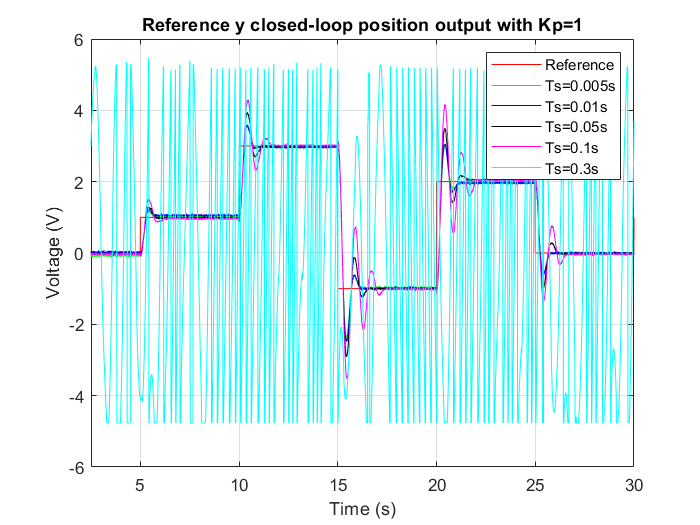

% Initialization of variables
Tg=0.005; % Graphing time [seg]
Ts=0.01; % Sampling time
Vmax=5; % [V]
Vmin=-5; % [V]

if useExperimentalData
    % Use Simulink 
    addpath([pwd filesep 'E6']);
    open P1_Ex6.slx
    run P1_Ex6.slx
else % Load variables
    FileName   = 'Ts005.mat';
    FolderName = [pwd filesep 'Common' filesep 'Resultados' filesep 'Prac1' filesep 'Ex6'];
    File       = fullfile(FolderName, FileName);
    load(File);   
    
    FileName   = 'Ts01.mat';
    FolderName = [pwd filesep 'Common' filesep 'Resultados' filesep 'Prac1' filesep 'Ex6'];
    File       = fullfile(FolderName, FileName);
    load(File);
    
    FileName   = 'Ts05.mat';
    FolderName = [pwd filesep 'Common' filesep 'Resultados' filesep 'Prac1' filesep 'Ex6'];
    File       = fullfile(FolderName, FileName);
    load(File);
    
    FileName   = 'Ts1.mat';
    FolderName = [pwd filesep 'Common' filesep 'Resultados' filesep 'Prac1' filesep 'Ex6'];
    File       = fullfile(FolderName, FileName);
    load(File);
    
    FileName   = 'Ts3.mat';
    FolderName = [pwd filesep 'Common' filesep 'Resultados' filesep 'Prac1' filesep 'Ex6'];
    File       = fullfile(FolderName, FileName);
    load(File);
end

% output
figure
plot(Ts005.time, [Ts005.signals.values(:,2,:)],'r')
hold all; grid on;
plot(Ts005.time, [Ts005.signals.values(:,3,:)],'g')
plot(Ts01.time, [Ts01.signals.values(:,3,:)],'b')
plot(Ts05.time, [Ts05.signals.values(:,3,:)],'k')
plot(Ts1.time, [Ts1.signals.values(:,3,:)],'m')
plot(Ts3.time, [Ts3.signals.values(:,3,:)],'c')
xlim([2.5 30]);
xlabel('Time (s)');
ylabel('Voltage (V)');
title('Reference y closed-loop position output with Kp=1');
legend('Reference','Ts=0.005s','Ts=0.01s','Ts=0.05s','Ts=0.1s','Ts=0.3s')

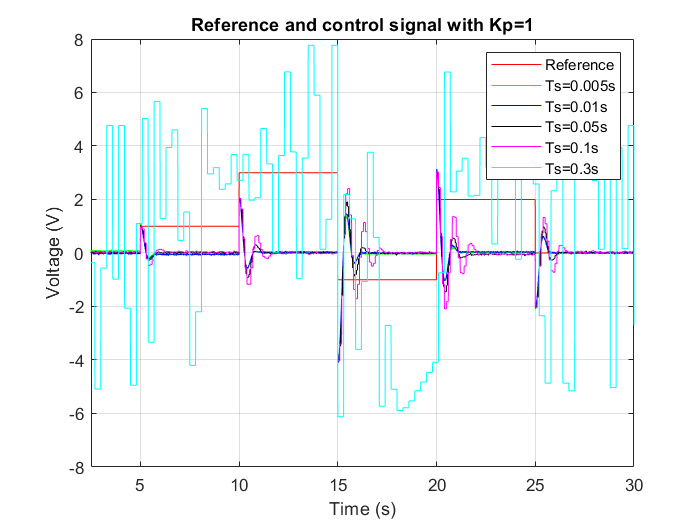


% error
figure
plot(Ts005.time, [Ts005.signals.values(:,2,:)],'r')
hold all; grid on;
plot(Ts005.time, [Ts005.signals.values(:,1,:)],'g')
plot(Ts01.time, [Ts01.signals.values(:,1,:)],'b')
plot(Ts05.time, [Ts05.signals.values(:,1,:)],'k')
plot(Ts1.time, [Ts1.signals.values(:,1,:)],'m')
plot(Ts3.time, [Ts3.signals.values(:,1,:)],'c')
xlim([2.5 30]);
xlabel('Time (s)');
ylabel('Voltage (V)');
title('Reference and control signal with Kp=1');
legend('Reference','Ts=0.005s','Ts=0.01s','Ts=0.05s','Ts=0.1s','Ts=0.3s')

In this case also, to analyze from what value the system will become unstable, as we have done previously, the plant has been discretized with the help of a zero-order holder. The closed-loop transfer function has been obtained and the poles analized evaluating the denominator by the Jury stability criterion. Thanks of it, we have obtained that the range of Ts for the system to be stable is from 0 to 0.3 seconds.